The following calculation makes use of the function describing the probability of finding a 

brownian particle innitially at position r_0 = 0 at another distance ds. I generalize this to n dimensions and assume isotropic diffusion.

$P\left(x_1 ,{\;x}_2 ,{\;\ldotp \ldotp \ldotp ,\;x}_n ,\;t\right)=\frac{1}{{\left(4\pi \textrm{Dt}\right)}^{\frac{n}{2}} }e^{-\frac{{\textrm{ds}}^2 }{4\textrm{Dt}}}$    the resulting mean squared displacement is $<r^2 >\;=2\textrm{nDt}$ 

FPS = 250; %Frames per second during acquisition
dt = 1/FPS;
disp(strcat('histograms are made measuring the spatial steps on a time interval of: ', num2str(1000/FPS), ' ms'))    

histograms are made measuring the spatial steps on a time interval of:4 ms


TrackNum = 1

TrackNum = 2

TrackNum = 3

TrackNum = 4

TrackNum = 5

TrackNum = 6

TrackNum = 7

TrackNum = 8

TrackNum = 9

TrackNum = 10

TrackNum = 11

TrackNum = 12

TrackNum = 13

TrackNum = 14

TrackNum = 15

TrackNum = 16

TrackNum = 17

TrackNum = 18

TrackNum = 19

TrackNum = 20

TrackNum = 21

TrackNum = 22

TrackNum = 23

TrackNum = 24

TrackNum = 25

TrackNum = 26

TrackNum = 27

TrackNum = 28

TrackNum = 29

TrackNum = 30

TrackNum = 31

TrackNum = 32

TrackNum = 33

TrackNum = 34

TrackNum = 35

TrackNum = 36

TrackNum = 37

TrackNum = 38

TrackNum = 39

TrackNum = 40

TrackNum = 41

TrackNum = 42

TrackNum = 43

TrackNum = 44

TrackNum = 45

TrackNum = 46

TrackNum = 47

TrackNum = 48

TrackNum = 49

TrackNum = 50

TrackNum = 51

TrackNum = 52

TrackNum = 53

TrackNum = 54

TrackNum = 55

TrackNum = 56

TrackNum = 57

TrackNum = 58

TrackNum = 59

TrackNum = 60

TrackNum = 61

TrackNum = 62

TrackNum = 63

TrackNum = 64

TrackNum = 65

TrackNum = 66

TrackNum = 67

TrackNum = 68

TrackNum = 69

TrackNum = 70

TrackNum = 71

TrackNum = 72

TrackNum = 73

TrackNum = 74

TrackNum = 75

TrackNum = 76

TrackNum = 77

TrackNum = 78

TrackNum = 79

TrackNum = 80

TrackNum = 81

TrackNum = 82

TrackNum = 83

TrackNum = 84

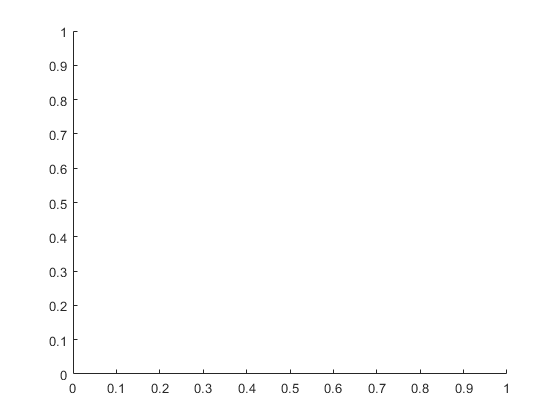

load('Tracks.mat')
Track = NaN(3,length(Tracks(1).Track(1,:)));
sigmax_all = [];
sigmay_all = [];
sigmaz_all = [];
BeadCounter = 0;
TotalNumberPoints = 0;
DiplayPlots = false;
for TrackNum = 1:length(Tracks)
    TrackNum
    Track(1,:) = Tracks(TrackNum).Track(1,:);
    Track(2,:) = Tracks(TrackNum).Track(2,:);
    Track(3,:) = Tracks(TrackNum).Track(3,:);    
    Grad = Track(:,2:end) - Track(:,1:(end-1));        
    StepDistribution = Grad(:,isfinite(Grad(3,:))); % Removing eventual data gaps
    NumberTimePoints = length(StepDistribution);
    if NumberTimePoints >= 250 % filtering short tracks that give poor statistics
        BeadCounter = BeadCounter + 1;
        TotalNumberPoints = TotalNumberPoints + NumberTimePoints;
        if DiplayPlots
            figure
            [sigmax] = MagicBrownian(StepDistribution(1,:),dt,'\Deltax (µm)',1);
            [sigmay] = MagicBrownian(StepDistribution(2,:),dt,'\Deltay (µm)',2);
            [sigmaz] = MagicBrownian(StepDistribution(3,:),dt,'\Deltaz (µm)',3);
        else
            [sigmax] = MagicBrownianNoDisplay(StepDistribution(1,:),dt);
            [sigmay] = MagicBrownianNoDisplay(StepDistribution(2,:),dt);
            [sigmaz] = MagicBrownianNoDisplay(StepDistribution(3,:),dt);
        end
            
        sigmax_all = [sigmax_all sigmax];
        sigmay_all = [sigmay_all sigmay];
        sigmaz_all = [sigmaz_all sigmaz];            
    end   
 end

## Overall statistics                              

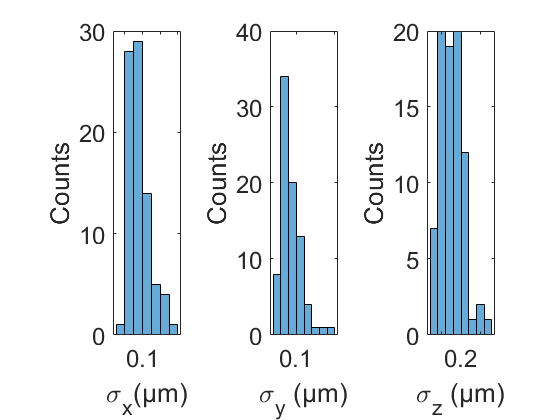

figure
subplot(1,3,1)
histogram(sigmax_all); 
xlabel('\sigma_x(µm)')
ylabel('Counts')
set(gca,'FontSize',18)
subplot(1,3,2)
histogram(sigmay_all); 
xlabel('\sigma_y (µm)')
ylabel('Counts')
set(gca,'FontSize',18)
subplot(1,3,3)
histogram(sigmaz_all); 
xlabel('\sigma_z (µm)')
ylabel('Counts')
set(gca,'FontSize',18)

mean_sigmax = mean(sigmax_all) 

mean_sigmax = 0.0965

sd_sigmax = std(sigmax_all) 

sd_sigmax = 0.0118

mean_sigmay = mean(sigmay_all) 

mean_sigmay = 0.0929

sd_sigmay = std(sigmay_all) 

sd_sigmay = 0.0133

mean_sigmaz = mean(sigmaz_all) 

mean_sigmaz = 0.1764

sd_sigmaz = std(sigmaz_all) 

sd_sigmaz = 0.0286

Kb = 1.38e-23; % in m^2*Kg*s^-2*K^-1
T = 273 +22; % in K
Eta = 0.95e-3;% in kg*m^-1*s^-1
D_Theory = Kb*T/(6*pi*Eta*250*1e-9) % in m^2/s. Here, 250*1e-9 corresponds to the bead radius in meters

D_Theory = 9.0936e-13

Theoretical_diffusive_sigma = sqrt(2*D_Theory*dt)*1e6 % in µm

Theoretical_diffusive_sigma = 0.0853

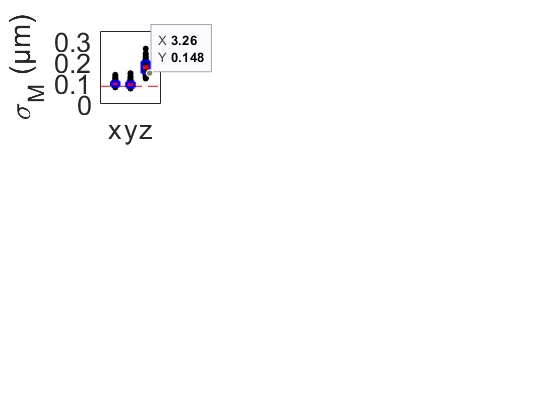


figure
plot([0 4], [Theoretical_diffusive_sigma Theoretical_diffusive_sigma], '--r')
hold on
BoxPlotStdv (sigmax_all,1,'x')
BoxPlotStdv (sigmay_all,2,'y')
BoxPlotStdv (sigmaz_all,3,'z')
ylabel('\sigma_M (µm)')
ylim([0 0.35])
xlim([0 4])
xticks([1 2 3])
yticks([0 0.1 0.2 0.3])
set(gca, 'FontSize', 20)


ExpectedPrecisionx = sqrt(mean_sigmax^2 - Theoretical_diffusive_sigma^2)

ExpectedPrecisionx = 0.0451

ExpectedPrecisiony = sqrt(mean_sigmay^2 - Theoretical_diffusive_sigma^2)

ExpectedPrecisiony = 0.0369

ExpectedPrecisionz = sqrt(mean_sigmaz^2 - Theoretical_diffusive_sigma^2)

ExpectedPrecisionz = 0.1544

BeadCounter

BeadCounter = 82

AverageTime = TotalNumberPoints/(BeadCounter*FPS) % in sec

AverageTime = 3.3093

The following function fits the distribution $P\left(x,t\right)=\frac{1}{{\left(4\pi \textrm{Dt}\right)}^{\frac{1}{2}} }e^{-\frac{{\textrm{dx}}^2 }{4\textrm{Dt}}}$ to the data. From this, it obtains the Diffusion coefficient

function [Sigma_Fit_Distribution] = MagicBrownian(DataIn,t,Label,SubplotDisplay)
    % input: t is in seconds
    %       DataIn is the spatial jumps between frames in micrometers
    subplot(1,3,SubplotDisplay);
    edges = [-1:0.05:1];
    h = histogram(DataIn,edges);
    hold on
    BinCenters = h.BinEdges(1:end-1) + (h.BinEdges(2) - h.BinEdges(1))/2;
    [xData, yData] = prepareCurveData(BinCenters, h.Values);
    
    % Set up fittype and options.
    ft = fittype( 'a*exp(-x^2/(4*Dt))', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [0 0];
    opts.StartPoint = [10 500];
    
    % Fit model to data.
    fitresult = fit( xData, yData, ft, opts );
    Dt = fitresult.Dt;
    Sigma_Fit_Distribution = sqrt(2*Dt); 
    plot( fitresult, xData, yData );
    legend off
    xlabel (Label)
    ylabel Counts
    xlim([-1 1])
    ylim([0 200])
    set(gca,'FontSize',14)
    return
end

function [Sigma_Fit_Distribution] = MagicBrownianNoDisplay(DataIn,t)
    % input: t is in seconds
    %       DataIn is the spatial jumps between frames in micrometers
    edges = [-1:0.05:1];
    [N,Edges] = histcounts(DataIn,edges);
    BinCenters = Edges(1:end-1) + (Edges(2) - Edges(1))/2;
    [xData, yData] = prepareCurveData(BinCenters, N);
    
    % Set up fittype and options.
    ft = fittype( 'a*exp(-x^2/(4*Dt))', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [0 0];
    opts.StartPoint = [10 500];
    
    % Fit model to data.
    fitresult = fit( xData, yData, ft, opts );
    Dt = fitresult.Dt;
    Sigma_Fit_Distribution = sqrt(2*Dt); 
    return
end